clc;
clear all

if isempty(gcp('nocreate'))  % Überprüft, ob bereits ein Parallel-Pool existiert
    parpool('local', 24);  % 4 Worker starten
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to parallel pool with 24 workers.



Multi-objective optimization:
5 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1           800                 1                 1
    2          1600         0.0752658          0.179849
    3          2400          0.059476           0.97554
    4          3200         0.0641068          0.963538
    5          4000         0.0751139           0.32469
    6          4800           0.06101          0.405769
    7          5600         0.0542372           0.92284
    8          6400         0.0431844          0.341391
    9          7200          0.037893          0.914327
   10          8000         0.0321355          0.351197
   11          8800         0.0300731          0.993334
   12          9600         0.0226304          0.32

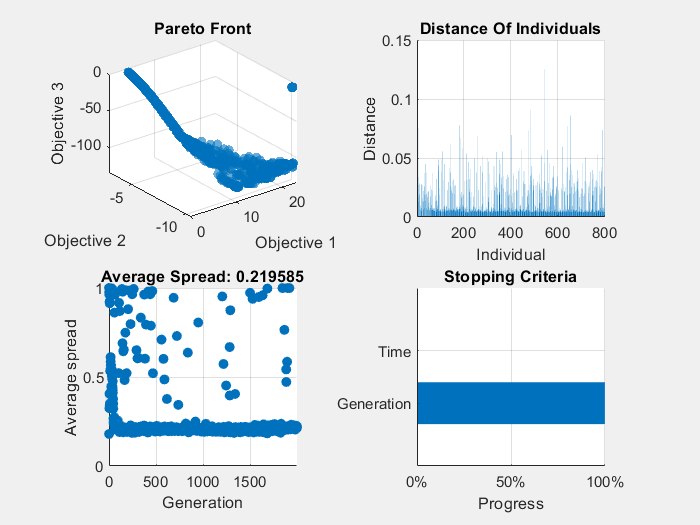


lb = [2.9, 4.25, 30, 0.1, 0.2];  % lower bounds 
ub = [4, 8, 60, 0.18, 0.3];       % upper bounds 



objective = @(x) obj_function(x);  % x = [L_f, L_s ,theta_fs]

options =  optimoptions('gamultiobj', ...
   'Display', 'iter', ...
   'PopulationSize', 800, ...
   'MaxGenerations', 2000, ...
   'ParetoFraction', 0.7, ...
   'CrossoverFraction', 0.95, ...
   'MutationFcn', {@mutationadaptfeasible, 0.35}, ...
   'FunctionTolerance', 1e-6, ...
   'MaxStallGenerations', 50, ...
   'MaxStallGenerations', 100, ... 
   'PlotFcn', {@gaplotpareto, @gaplotparetodistance, @gaplotspread, @gaplotstopping}, ...
   'UseParallel', true);             
            
[x_opt, fval] = gamultiobj(objective, 5,[], [], [], [], lb, ub, [], options);

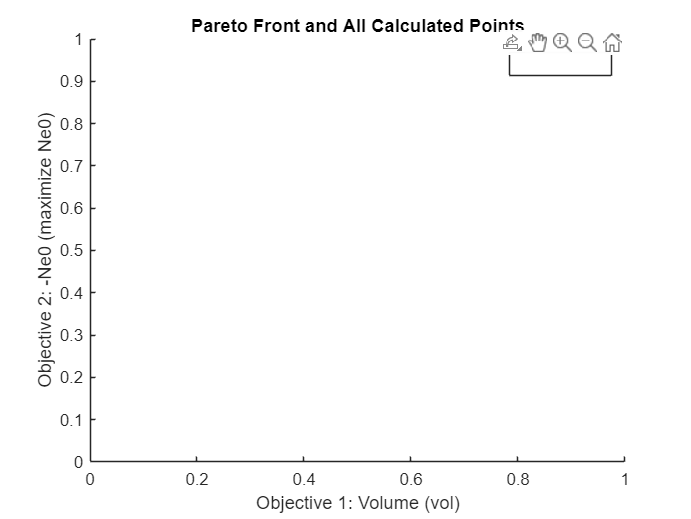


figure;
hold on;

xlabel('Objective 1: Volume (vol)');
ylabel('Objective 2: -Ne0 (maximize Ne0)');
legend;
title('Pareto Front and All Calculated Points');
hold off;

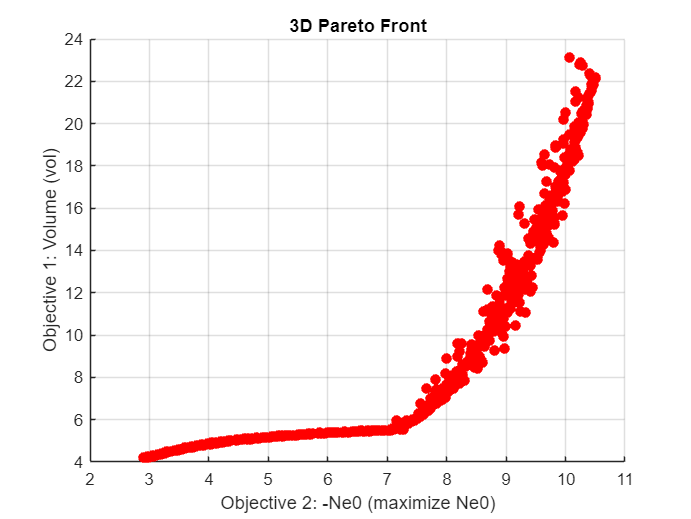


L_f_opt = x_opt(:, 1);
L_s_opt = x_opt(:, 2);
theta_fs_opt = x_opt(:, 3);
scl_t_f = x_opt(:, 4);
scl_L_j = x_opt(:, 5);


figure;
hold on
scatter3(abs(fval(:,2)), fval(:,1), abs(fval(:,3)), 40, 'red', 'filled');
xlabel('Objective 2: -Ne0 (maximize Ne0)');
ylabel('Objective 1: Volume (vol)');
zlabel('Objective 3: -z_max (maximize z_max');
title('3D Pareto Front');
grid on;

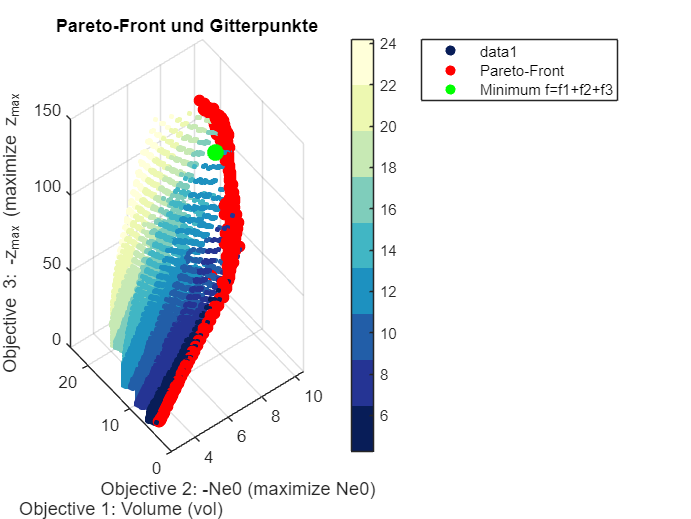



% Gitter für die Zielfunktionsauswertung erstellen
h = 0.5;  % Maschenweite
h1 = 0.05;
[x1_grid, x2_grid, x3_grid, x4_grid, x5_grid] = ndgrid(lb(1):h:ub(1), lb(2):h:ub(2),lb(3):h:ub(3),lb(4):h1:ub(4),lb(5):h1:ub(5));
f1_grid = zeros(size(x1_grid));
f2_grid = zeros(size(x1_grid));
f3_grid = zeros(size(x1_grid));

% Gewichte definieren
w1 = 1;  % Gewicht für f1
w2 = 1;  % Gewicht für f2
w3 = 100;  % Gewicht für f3

% Berechnung der Zielfunktionen auf dem Gitter
% Gittergröße bestimmen
[numRows, numCols, numLayers] = size(x1_grid);

% Initialisiere die Ergebnisarrays
f1_grid = zeros(numRows, numCols, numLayers);
f2_grid = zeros(numRows, numCols, numLayers);
f3_grid = zeros(numRows, numCols, numLayers);
f_weighted_grid = zeros(numRows, numCols, numLayers);

% Starte parallele Berechnung
%parpool; % Starte den Parallelpool, falls noch nicht aktiv (wenn ohne GaMult)
parfor idx = 1:numel(x1_grid)
    x = [x1_grid(idx), x2_grid(idx), x3_grid(idx), x4_grid(idx), x5_grid(idx)];
    f = objective(x);  % Berechne Zielfunktion für diesen Punkt
    f1_grid(idx) = f(1);
    f2_grid(idx) = f(2);
    f3_grid(idx) = f(3);
    f_weighted_grid(idx) = w1 * f(1) + w2 * f(2) + w3 * f(3);
end

% Definierte RGB-Werte in der Notation 'rgb(r,g,b)'
rgb_colors = {'rgb(255,255,217)', 'rgb(237,248,177)', 'rgb(199,233,180)', ...
              'rgb(127,205,187)', 'rgb(65,182,196)', 'rgb(29,145,192)', ...
              'rgb(34,94,168)', 'rgb(37,52,148)', 'rgb(8,29,88)'};

% Umwandlung in eine MATLAB-kompatible Colormap (Nx3-Matrix)
my_colormap = zeros(length(rgb_colors), 3);  % Initialisiere die Colormap
for i = 1:length(rgb_colors)
    my_colormap(i, :) = parse_rgb_string(rgb_colors{i});
end
my_colormap = flipud(my_colormap);
% Gitterdaten in eine Punktwolke umwandeln
f1_vals = f1_grid(:);
f2_vals = f2_grid(:);
f3_vals = f3_grid(:);
f_weighted_vals = f_weighted_grid(:);

% Minimum von f = f1 + f2 + f3 suchen
[f_min, min_idx] = min(f_weighted_vals);  % Minimum und Index bestimmen
x1_min = x1_grid(min_idx);           % x1-Wert des Minimums
x2_min = x2_grid(min_idx);           % x2-Wert des Minimums
x3_min = x3_grid(min_idx);           % x3-Wert des Minimums
x4_min = x4_grid(min_idx);           % x4-Wert des Minimums
x5_min = x5_grid(min_idx);           % x5-Wert des Minimums
% 3D-Pareto-Front und Gitterpunkte plotten
color_values = f1_vals;  % Farbgebung basierend auf f1

%Plot
figure;
scatter3(abs(f2_vals),f1_vals, abs(f3_vals), 10, color_values, 'filled');  % Farbgebung durch color_values
colormap(my_colormap);  % Benutzerdefinierte Colormap anwenden
colorbar;  % Farbbalken anzeigen
hold on
scatter3(abs(fval(:,2)), fval(:,1), abs(fval(:,3)), 50, 'red', 'filled', 'DisplayName', 'Pareto-Front');
scatter3(abs(f2_grid(min_idx)),f1_grid(min_idx), abs(f3_grid(min_idx)), 100, 'green', 'filled', 'DisplayName', 'Minimum f=f1+f2+f3');
xlabel('Objective 2: -Ne0 (maximize Ne0)');
ylabel('Objective 1: Volume (vol)');
zlabel('Objective 3: -z_max (maximize z_max');
title('Pareto-Front und Gitterpunkte');
legend;
grid on;

function rgb = parse_rgb_string(rgb_string)
    % Entferne 'rgb(' und ')' aus dem String
    rgb_string = strrep(rgb_string, 'rgb(', '');
    rgb_string = strrep(rgb_string, ')', '');
    
    % Splitte die RGB-Werte in numerische Komponenten
    rgb_values = sscanf(rgb_string, '%d,%d,%d');
    
    % Normalisiere auf den Bereich [0, 1]
    rgb = rgb_values' / 255;
end


function f = obj_function(x)
   
    L_f = x(1);
    L_s = x(2);
    theta_fs = x(3);
    scl_t_f = x(4);
    scl_L_j =x(5);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  
    b=0.1;
	Nc=12;
	En=1;
	su0=2;
	k=1.6;
	S_t=3;
	m=1.56;
	n=4.19;
	p=1.57;
	q=4.43;
	%theta_fs=50;
	theta_ai=1;
	t_f_by_L_f=scl_t_f;
	w_f_by_L_f=1;
	L_j_by_L_f=scl_L_j;


	ds=0.01;
	max_step=120000;
	tol=10;


	theta_af_step = deg2rad(1);

	alpha = 1 / S_t;
	N_nmax = 3 * pi + 2 + (t_f_by_L_f) * (alpha + ((1 + alpha) / sqrt(2))); % Scalar
	N_tmax = 2 * alpha + 15 * (t_f_by_L_f); % Scalar
	N_mmax = (pi / 2) * (1 + (t_f_by_L_f) ^ 2); % Scalar

	Ne_max_global = 0;
	Ne_results = [];

    L_j = L_f * L_j_by_L_f;
   	t_f = L_f * t_f_by_L_f;
    w_f = L_f * w_f_by_L_f;
    
        theta_ca = atan((L_s * sind(theta_fs)) / (L_j + L_s * cosd(theta_fs) - L_f / 2));
        L_ca = L_s * sind(theta_fs) / sin(theta_ca);
        
        for theta_af = 0:theta_af_step:deg2rad(90)
            c1 = sin(theta_af);
            c2 = cos(theta_af);
            c3 = (L_ca / L_f) * (cos(theta_af) * sin(theta_ca) - sin(theta_af) * cos(theta_ca));

            %%%%%%%%%%NEW
            Net = N_tmax / abs(c2);
            %%%%%%%%%%NEWEnde   
            Ne = 0;
            f_Ne = 1e10;
            
            for Ne_cand = 0:0.001:12
                f = (abs(c1) * Ne_cand / N_nmax) ^ q + ...
                    ((abs(c3) * Ne_cand / N_mmax) ^ m + ...
                    (abs(c2) * Ne / N_tmax) ^ n) ^ (1 / p) - 1;
                
                if abs(f) < abs(f_Ne)
                    f_Ne = f;
                    Ne = Ne_cand;
                end
            end
            
            Ne_max_global = max(Ne_max_global, Ne);
            
            vol = (L_f + sind(theta_fs) * L_s) * t_f * w_f;
            
            Ne_results = [Ne_results; L_f, L_s, vol, rad2deg(theta_af), Ne_max_global, f_Ne, Net];
        end

	Ne_max = Ne_max_global;
	%disp('Computation complete.');

        L_j = L_f * L_j_by_L_f;
        t_f = L_f * t_f_by_L_f;
        w_f = L_f * w_f_by_L_f;
       
       %vol = (L_f + sind(theta_fs) * L_s) * t_f * w_f;
         
	num_rows = size(Ne_results, 1);

	Ne_input_depth_results = [];

	for i = 1:num_rows
   	 L_f = Ne_results(i, 1);
   	 L_s = Ne_results(i, 2);
   	 vol = Ne_results(i, 3);
  	 Ne_max = Ne_results(i, 5);  % Maximales Ne für diese Zeile
  	 [~, Ne0_idx] = min(abs(Ne_results(:, 5) - Ne_results(:, 7)));
  	 Ne0 = Ne_results(Ne0_idx, 5);  % Ne für den minimalen Unterschied
  	 theta_af0 = deg2rad(Ne0_idx - 1);  % Winkel in Grad umwandeln
 	 Ne_input_depth_results = [Ne_input_depth_results; L_f, L_s, vol, Ne_max, Ne0, rad2deg(theta_af0)];
	end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  
    %vol = (L_f + sind(theta_fs) * L_s) * t_f * w_f;  

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  
    Ne0 = Ne_input_depth_results(1,5);
	theta_af0 = deg2rad(Ne_input_depth_results(1,6));

	alpha = 1 / S_t;
	L_j = L_f * L_j_by_L_f;
	t_f = L_f * t_f_by_L_f;
	w_f = L_f * w_f_by_L_f;

	A_f = L_f * w_f; % Scalar multiplication
	theta_a = deg2rad(theta_ai); % Now a scalar

    
    theta_ca = atan((L_s * sind(theta_fs)) / (L_j + L_s * cosd(theta_fs) - L_f / 2));
    L_ca = L_s * sind(theta_fs) / sin(theta_ca);

	N_nmax = 3 * (pi) + 2 + (t_f_by_L_f) * (alpha + ((1 + alpha) / sqrt(2))); % SCALAR
	N_tmax = 2 * alpha + 15 * (t_f_by_L_f); % SCALAR
	N_mmax = ((pi) / 2) * (1 + (t_f_by_L_f)^2); % SCALAR

	c1 = sin(theta_af0);
	c2 = cos(theta_af0); 
	c3 = L_ca / L_f * (cos(theta_af0) * sin(theta_ca) - sin(theta_af0) * cos(theta_ca));

	x_pos = 0; % Initialize as scalar
	z_pos = -0.1; % Initialize as scalar
	theta_f = theta_af0 - theta_a;
	Rnt0 = ((N_tmax / N_nmax) * (p * q / n)) / ((abs(Ne0 * c3) / N_mmax).^m + (abs(Ne0 * c2) / N_tmax).^n).^(1/p - 1) ...
     * (abs(Ne0 * c1) / N_nmax).^(q - 1) / (abs(Ne0 * c2) / N_tmax).^(n - 1);

	su = su0; % Now a scalar

	x_rec = zeros(1, 1, max_step); % Adjust dimensions for scalar usage
	z_rec = zeros(1, 1, max_step); 
	theta_a_rec = zeros(1, 1, max_step); 
	theta_f_rec = zeros(1, 1, max_step); 

	ds = ds; En = En; k = k; 
	su0 = su0; Nc = Nc; b = b;
	max_step = max_step;
	x = 0; z = 0; % initial pos

	for i = 1:max_step
   	 % keyed anchors
   	 dx = ds * cos(theta_f) + ds * Rnt0 * sin(theta_f);
  	  dz = ds * sin(theta_f) - ds * Rnt0 * cos(theta_f);

  	  dtheta_adz = 1 / theta_a * (En * Nc * b / Ne0 / A_f - k * theta_a^2 / (2 * su));
	    dtheta_a = dtheta_adz * dz;
	
 	   theta_a = theta_a + dtheta_a;
 	   theta_f = theta_f - dtheta_a;

  	   x = x + dx;
	   z = z + dz;

 	   su = su0 + k * z;

  	   x_rec(:,:,i) = x;
 	   z_rec(:,:,i) = z;
  	  theta_a_rec(:,:,i) = theta_a;
  	  theta_f_rec(:,:,i) = theta_f; 
	end

	z_max = -max(z_rec);  %TODO: k.A. ob das stimmt // schauen, wie in Alex ursprünglichen Code
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  

    f(1) = vol;        % Objective 1: minimize volume
    f(2) = -Ne_max;    % Objective 2: maximize Ne0 (we minimize -Ne0 to maximize it)
    f(3) = z_max;     % 

end

